clc;
clear;
close all;

## 添加路径

addpath('plane wave\')
addpath('镜头\')

## 参数设置

# Gaussian Beam

lambda=647e-6;
beamSize=flip(linspace(1,10,21));
beamStd=max(beamSize)/2.85;
noise=0.05;
beamAmp=1;
color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, ...
    'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

u=zeros(length(beamSize),length(noise));
sigma=u;
FN=u;
N_percent=u;
jj=1;



# MLA

rla1=-1.1;
d1=0.15;
N=40;
rate=d1/N;
t = 1.2;% 透镜厚度
material={"F_SILICA"};
MLA1=Lens([rla1,inf],t,d1,material,lambda);
f=focalLength(MLA1);
MLA2=Lens([inf,-rla1],t,d1,material,lambda);


num=round(beamStd./d1*5);            %数量
if num==0
    num=1;
end
area1 = num.*d1;           % 光场的面积
area2=12.8;
area3=12.8;
area2=findClosestDivisible(area2,rate);

distance1 = 1;   % 投影距离
distance2 = 70;   % 投影距离
distance3 = 74.9;


# Diffuser

rpm=50000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=22;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;%线速度
deltat=1;%
T=100;%积分时间（μs）
times=floor(T/deltat);
route=velocity*T;
if route>2*pi*radius_diffuser
    route=2*pi*radius_diffuser;
    T=route/velocity;
    times=floor(T/deltat);
end
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
szz=[round(route/rate)+N*num,N*num];
phase=Diffuser.generateDiffuser(diffuser,rate,szz);

# Fourier Lens

Dfl = area2;              %采样区域
file='OLD2440-T2M(JCOPTIX-F=74.9胶合).txt';
FL=readLens(file,lambda);

## 生成透镜相位

Lens.lensArrayThickFcn(MLA1,N,num,'square');
Lens.lensArrayThickFcn(MLA2,N,num,'square');
Lens.lensThickFcn(FL,Dfl,round(area2/rate));


Lens.lensSingle(MLA1)
Lens.lensSingle(MLA2)
Lens.lensSingle(FL);
Diffuser.diffuserSingle(diffuser)
distance2= single(distance2);
distance3= single(distance3);
area1= single(area1);
area2= single(area2);
area3= single(area3);

if canUseGPU
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(MLA2)
    Lens.lensGPUArray(FL)
    Diffuser.diffuserGPUArray(diffuser)
    distance2= gpuArray(distance2);
    distance3= gpuArray(distance3);
    area1= gpuArray(area1);
    area2= gpuArray(area2);
    area3= gpuArray(area3);
end
lensgroup={MLA1,MLA2,FL};
area=[area1,area1,area2,area3];
distance=[20,distance1,distance2,distance3];


for noise1=noise
    kk=1;
    for beamSize1=beamSize
        


# Beam

        beamStd=beamSize1/2.85;
        beam=GaussianBeam(beamAmp,beamStd,lambda);
        beams=GaussianBeam.defocused(beam,10,N*num,rate);
        I=zeros(round(area3/rate));

## 光场变换

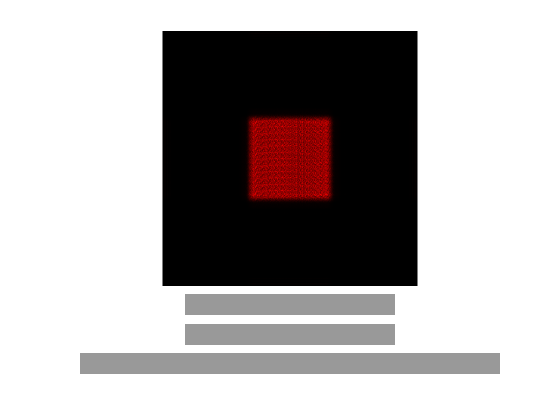

        
        for ii=1:times
            %叠加噪声
            beamss=GaussianBeam.beamNoise(beams,noise1,0);
            F = transform(beamss, area1, lambda, 30, [rate, rate]);
            index=round((velocity*(ii-1)*deltat)/rate+1);
            F=F.*phase(index:index+size(F,1)-1,:);
            F=ASMlensgroup(F,lensgroup,distance,area,lambda,rate);
        
            I_now=abs(F).^2;
            I = I+I_now;
            subplot(12,10,[91,100])
            progressBar([100,1000],ii/times)
            drawnow
        end
        Inorm=imnorm(I);
        figure(1)
        subplot(12,10,[1,90])
        imshow(uint16(Inorm*65536),mymap)
        if jj==1&&kk==1
            threshold=otsuthresh(imhist(Inorm));
            im2=Inorm>threshold;
        end
        [u(kk,jj),sigma(kk,jj),N_percent(kk,jj)]=homoanalyse3(Inorm,im2);   
        imwrite(Inorm,['BS2\B=' num2str(beamSize1/2/d1) '.bmp'])
        
        figure(1)
        subplot(12,10,[101,110])
        progressBar([100,1000],kk/length(sigma));

        kk=kk+1;
    end
    
    jj=jj+1;
    figure(1)
    subplot(12,10,[111,120])
    progressBar([100,1000],jj/length(noise));
end

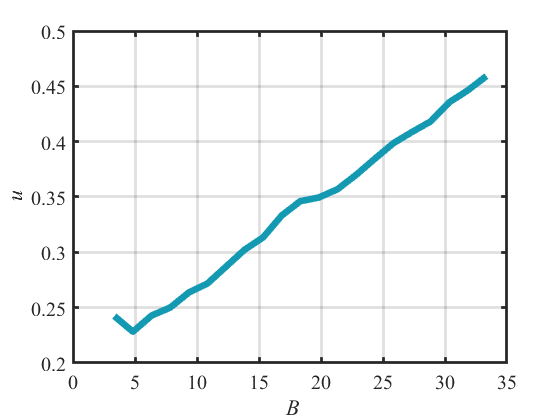


figure
B=beamSize/2/d1;
u1=u;
sigma1=sigma;
N_percent1=N_percent;
load('E:\code\Matlab\资料\color_2.mat');
plot(B,u1,'linewidth',5,'Color',color5)
xlabel('\it B')
ylabel('\it u')
set(gca,'Fontname','Times New Roman','FontSize',15,'linewidth',2)
grid on

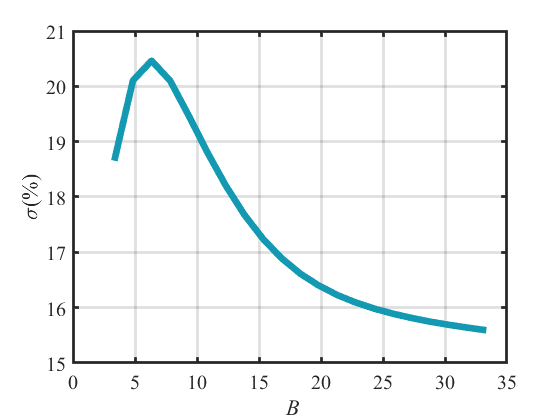

figure
plot(B,sigma1,'linewidth',5,'Color',color5)
ylabel('\sigma(%)')
xlabel('\it B')
grid on
set(gca,'Fontname','Times New Roman','FontSize',15,'linewidth',2)

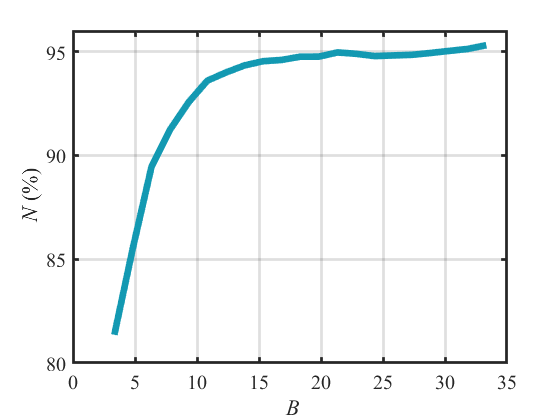

figure
plot(B,N_percent1,'linewidth',5,'Color',color5)
ylabel('\it N \rm(%)')
xlabel('\it B')
grid on
set(gca,'Fontname','Times New Roman','FontSize',15,'linewidth',2)